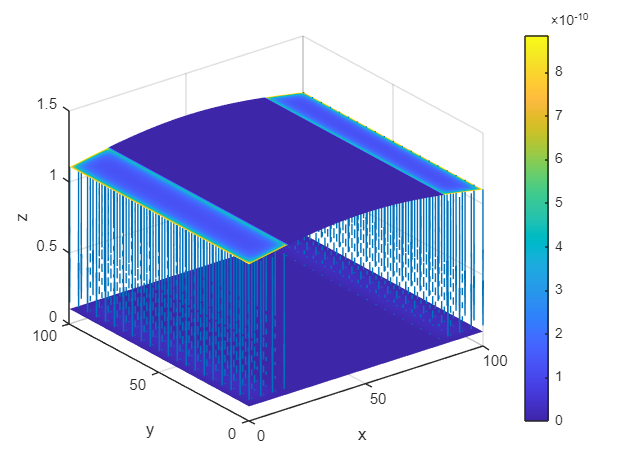

% A computational tool to calculate the capacitance of two plates
% using the Finite Difference Method (FDM)

% Example test file: 100mx100m Rectangular Plates of 1m plate separation
% Sinusoidal top plate, 1 bump, 0.1m amplitude
% Mesh size 100, mesh size 10 in Z direction
% To test different bump numbers, change the coefficient for kx_top to the
% desired number of bumps

clear;
clc;

% Grid dimensions - number of points
xdim=100;
ydim=100;
zdim=11; % real z dimension (plate separation) will be zdim - 1
        % the extra 1 is to account for plate height 
        % fluctuations (eg sinusodal plates). For fluctuations that
        % are more than one grid dimension, increase this and adjust 
        % the code for caluclating area and distance accordingly
dx = 1; % grid spacing (m), used for calculating the areas and distances
dy = 1;
dz = 0.1;

% Initialize voltage matrix
V_now=zeros(xdim+1, ydim+1, zdim+1);

% Define voltage of top plate
V_top = 10;

% Define functions for boundary conditions (non-parallel capacitor plates)
x = (0:xdim) * dx;
y = (0:ydim) * dy;
[X, Y] = meshgrid(x, y);

% BC functions for z position of sinusodal plates
% Comment out accordingly to choose what surface you wish to use
A_top  = 0.1;                 % amplitude (m)
z0_top = zdim*dz;            % mean height (m)
kx_top = 1*pi / (xdim*dx);          % wavelength is 2pi/k
ky_top = 1*pi / y(end);
Zsurf_top = z0_top + A_top * sin(kx_top * X); % only x direction
%Zsurf_top = z0_top + A_top * sin(kx_top * X) .* sin(ky_top * Y);

A_bottom  = 0.5;            % amplitude (m)
z0_bottom = dz;                 % mean height (m)
kx_bottom = 30*pi / x(end);      % wavelength fits domain
ky_bottom = 1*pi / y(end);
Zsurf_bottom = z0_bottom + A_bottom * sin(kx_bottom * X); % only x direction
Zsurf_bottom = z0_bottom + A_bottom * sin(kx_bottom * X) .* sin(ky_bottom * Y);

% BC functions for z position of parallel plates
%Zsurf_top = zdim*dz*ones(xdim+1, ydim+1);
Zsurf_bottom = dz*ones(xdim+1, ydim+1);

% BC for eliptical plate
elliptical = false; % Set to true if you wish to have the plate as an ellipse instead of rectangle
if elliptical
    a = xdim/2;   % semi-major axis (x)
    b = ydim/2;   % semi-minor axis (y)
    
    inEllipse = ((X-a).^2)/(a^2) + ((Y-b).^2)/(b^2) <= 1;
    Zsurf_top(~inEllipse) = NaN;
    Zsurf_bottom(~inEllipse) = NaN;
end

% Initialize boundary conditions (capacitor plates)
k_surf_top = round(Zsurf_top/dz) + 1; % round top surface indicies to nearest grid point
% Initialize all top plate grid points to V_top
for i = 1:xdim+1
    for j = 1:ydim+1
        k = k_surf_top(i, j);
        if k >= 1 && k <= zdim+1
            if elliptical
                a = xdim/2;
                b = ydim/2;
                if (i-a)^2/a^2 + (j-b)^2/b^2 <= 1
                    V_now(i, j, k) = V_top;
                end
            else
                V_now(i, j, k) = V_top;
            end
        end
    end
end
k_surf_bottom = round(Zsurf_bottom/dz) + 1; % round bottom surface indicies to nearest grid point
% Initialize all bottom plate grid points to 0
for i = 1:xdim+1
    for j = 1:ydim+1
        k = k_surf_bottom(i, j);
        if k >= 1 && k <= zdim+1
            if elliptical
                a = xdim/2;
                b = ydim/2;
                if (i-a)^2/a^2 + (j-b)^2/b^2 <= 1
                    V_now(i, j, k) = 0;
                end
            else
                V_now(i, j, k) = 0;
            end
        end
    end
end

% Iteration counter
iter=0;

% Calculation of maximum error between V_now and V_prev at all points
% By setting the applied voltage for only V_now, we have made V_now and
% V_prev different, hence error will be greater than zero and the program
% will enter the while loop following this command.
V_prev = V_now;
error=1;%max(max(abs(V_now-V_prev)));

% Fix the boundary conditions and only solve for between plates
k_surf_top = round(Zsurf_top/dz) + 1;
k_surf_bottom = round(Zsurf_bottom/dz) + 1;
fixed = false(xdim+1, ydim+1, zdim+1);
solve = false(xdim+1, ydim+1, zdim+1);
for i = 1:xdim+1
    for j = 1:ydim+1
        kb = k_surf_bottom(i,j); % grid indices of bottom plate
        kt = k_surf_top(i,j); % grid indices of top plate

        if kb >= 1 && kb <= zdim+1
            fixed(i,j,kb) = true;
            V_prev(i,j,kb) = 0; % fix bottom plate to V = 0
        end
        if kt >= 1 && kt <= zdim+1
            fixed(i,j,kt) = true;
            V_prev(i,j,kt) = V_top; % fix top plate to V = V_top
        end
        if kb < kt && kb >= 1 && kt <= zdim+1
            if elliptical
                a = xdim/2;
                b = ydim/2;
                if (i-a)^2/a^2 + (j-b)^2/b^2 <= 1
                    solve(i,j,kb+1:kt-1) = true; % only solve points that are between the plates and inside the ellipse
                end
            else
                solve(i,j,kb+1:kt-1) = true; % if not ellipse, solve for all points that are between the plates
            end
        end
    end
end

% Iteration loop
while(error>0.01)% Run this until convergence
    
    iter=iter+1; % Iteration counter increment
    
    % Updating present iteration using 6 point central diffrence (Taylor series) form
    % of Laplace equation obtained using Finite Difference Method
    for i = 2:xdim
        for j = 2:ydim
            for k = 2:zdim
                if solve(i,j,k) && ~fixed(i,j,k) % only update if solve = true and fixed = false
                    V_now(i, j, k) = (V_prev(i-1, j, k)+V_prev(i+1, j, k)+V_prev(i, j-1, k)+V_prev(i, j+1, k)+V_prev(i, j, k-1)+V_prev(i, j, k+1))/6;
                end
            end
        end
    end

    error=max(max(abs(V_now(:)-V_prev(:)))); % Calculate the maximum error between previous and current iteration at all points
    V_prev=V_now; % Updating previous iteration matrix to the last iteration performed
end

% Calculate electric field, E
figure;
[ex, ey, ez]=gradient(V_now, dx, dy, dz); % E, electric field
ex = -ex;
ey = -ey;
ez = -ez;

% Calculate charge density (rho)
epsilon0 = 8.854e-12;           % Air permittivity
Ex_top = zeros(xdim+1, ydim+1);
Ey_top = zeros(xdim+1, ydim+1);
Ez_top = zeros(xdim+1, ydim+1);
Ez_bot = zeros(xdim+1, ydim+1);
for i = 1:xdim+1
    for j = 1:ydim+1
        k_top = k_surf_top(i, j);
        k_bot = k_surf_bottom(i, j);
        if k_bot >= 1 && k_bot<k_top && k_top <= zdim+1
            Ez_top(i, j) = -ez(i, j, k_top);
            Ez_bot(i, j) = -ez(i, j, k_bot);
        end
    end
end
% Take rho as normal component of divergence of electric field on the surfaces
% Mostly accurate for parallel plates, less so for sinusoid or curved plates
rho_top = epsilon0 * Ez_top;        % top surface charge density (C/m^2)
rho_bot = epsilon0 * Ez_bot;        % bottom surface charge density (C/m^2)


% Plot the electric field distribution, charge density, and surfaces
[x, y, z] = meshgrid((0:size(V_now, 2)-1)*dx, (0:size(V_now,1)-1)*dy, (0:size(V_now,3)-1)*dz);

% Calculate the charge density colormap
Colour_top = abs(rho_top); % making a color matrix using the charge density
Colour_bot = abs(rho_bot); 

stepx = 5;   % x direction (every stepx'th point), change accordingly based on xdim
stepy = 5;   % y direction (every stepy'th point), change accordingly based on ydim
stepz = 1;   % z direction (keep all)

xs  = x(1:stepy:end, 1:stepx:end, 1:stepz:end);
ys  = y(1:stepy:end, 1:stepx:end, 1:stepz:end);
zs  = z(1:stepy:end, 1:stepx:end, 1:stepz:end);

exs = ex(1:stepy:end, 1:stepx:end, 1:stepz:end);
eys = ey(1:stepy:end, 1:stepx:end, 1:stepz:end);
ezs = ez(1:stepy:end, 1:stepx:end, 1:stepz:end);

h = quiver3(xs, ys, zs, exs, eys, ezs, 0.2); % quiver3 command creates a plot of E=-grad(V)
hold on
xlabel('x'); ylabel('y'); zlabel('z')

% Plot surfaces with charge density colourmap
surf(X, Y, Zsurf_top, Colour_top)
hold on
surf(X, Y, Zsurf_bottom, Colour_bot)
colorbar;
xlabel('x'); ylabel('y'); zlabel('z')
shading interp
hold off


% Calculate capacitance
C_top = sum(sum(rho_top./V_top)*dx*dy(:)) % Integrate over top surface and divide by potential difference (V_top)

C_top = 9.2567e-08

C_bot = sum(sum(rho_bot./V_top)*dx*dy(:)) % Integrate over bottom surface and divide by potential difference (V_top)

C_bot = 5.6357e-09

C_avg = (abs(C_top)+abs(C_bot))/2

C_avg = 4.9101e-08

Percent_difference = abs(abs(C_top)-abs(C_bot))/abs(C_top)+abs(C_bot)*200

Percent_difference = 0.9391

if elliptical
    A = pi*xdim*dx*ydim*dy/4; % plate area (ellipse)
else
    A = (xdim*dx) * (ydim*dy); % plate area (rectangle)
end
C_theoretical = epsilon0 * A / ((zdim-1)*dz) % for testing purposes, not accurate for curved plates

C_theoretical = 8.8540e-08